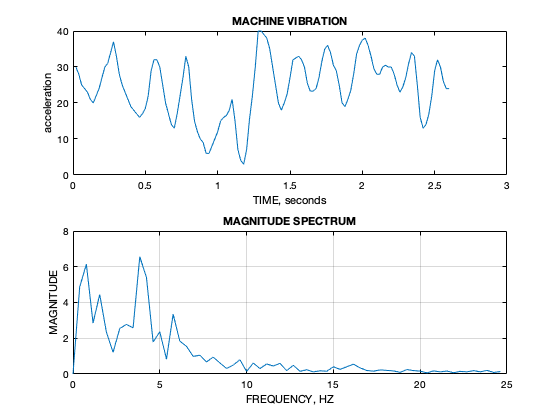

%dft.m
%Basic estimating the dft of signal
clear all;
close all;
load VIB.DAT;

T = 0.02; % Time spacing in seconds
fs = 1/T; % sampling Freq. in Hz

N = length(VIB); % Number of datapoints
t = (1:N)'*T; % Time axis
figure(1); subplot(2,1,1); plot(t,VIB)
title('MACHINE VIBRATION'); xlabel('TIME, seconds');
ylabel('acceleration')

vibdt = detrend(VIB); % remove average value
win = hamming(N); % Windowing (Hamming Window)
vibdw = vibdt.*win; % dot product multiplication

%Estimate DFT of Vib Signal
vib = T*fft(vibdt); 

magvib = abs(vib(1:N/2));
fd = 1/(N*T); 
f=(0:N/2-1)*fd; 
subplot(2,1,2); plot(f,magvib); grid
title("MAGNITUDE SPECTRUM"); xlabel("FREQUENCY, HZ");
ylabel("MAGNITUDE")

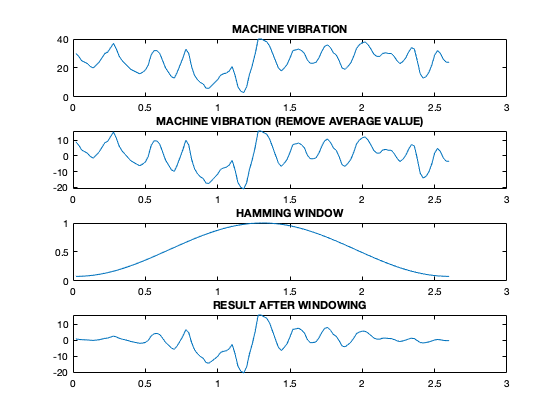


% plot processed signals
figure(2)
subplot(411); plot(t,VIB)
title('MACHINE VIBRATION');
subplot(412); plot(t,vibdt)
title("MACHINE VIBRATION (REMOVE AVERAGE VALUE)");
subplot(413); plot(t, win)
title("HAMMING WINDOW");
subplot(414); plot(t,vibdw)
title("RESULT AFTER WINDOWING");

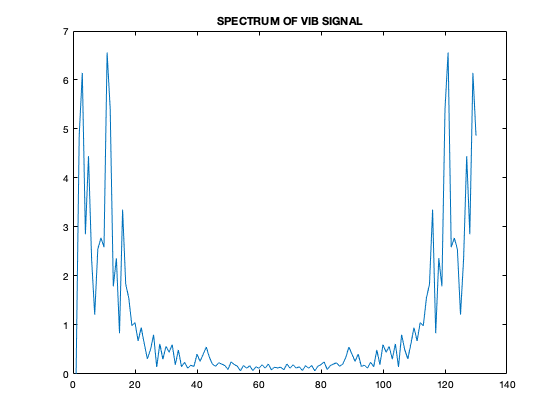


% Spectrum of vibration signal
figure(3)
magvib = abs(vib);
plot(magvib)
title('SPECTRUM OF VIB SIGNAL')